# **RS-MILP-01: Configure Optimization Problem from Contact Matrix**

**University of Texas at Austin**

**Department of Aerospace Engineering and Engineering Mechanics**

**Hongseok Kim**

## **1. Generate A matrix from contact chart**

clear;
clc;


addpath('/Library/gurobi1300/macos_universal2/matlab')
savepath

addpath ~/Desktop/Redstone_MILP/RS_MILP_01_Config_MILP/
load('EOIR_48_SATs_12_Orbit_Planes_98_inc_7days_access_interval.mat','EOIR_access_interval')


% 기준 시각 정의

T = EOIR_access_interval;

t0 = datetime(2030, 1, 1, 0, 0, 0,'TimeZone','UTC');

% --- Source / Target을 string으로 통일 ---
src = string(T.Source);
tgt = string(T.Target);

% --- Ground 번호 추출 ---
gTok = regexp(src, 'Ground[_\s]*Point[_\s]*(\d+)', 'tokens', 'once');
groundNum = cellfun(@(c) str2double(c{1}), gTok);

% --- Satellite 번호 추출 ---
sTok = regexp(tgt, '(?i)SAT[^0-9]*(\d+)', 'tokens', 'once');
satNum = cellfun(@(c) str2double(c{1}), sTok);

% --- Start / End → datetime ---
st = T.StartTime;
en = T.EndTime;

if ~isdatetime(st)
    st = datetime(string(st), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end
if ~isdatetime(en)
    en = datetime(string(en), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end

% --- 중간 시각 ---
midTime = st + (en - st)/2;

% --- 기준 시각 대비 초(second) 차이 → integer ---
timeSec = seconds(midTime - t0);
timeSec = double(round(timeSec));   % 정수화 (필요시 floor / ceil로 변경 가능)


contact_index = (1:length(st))';

% --- 최종 3-column matrix ---
A_matrix = [double(satNum), double(groundNum), timeSec, contact_index];

A_matrix = sortrows(A_matrix, 3);

A_matrix = A_matrix(1:400,:);
Original_A = T(A_matrix(:,4),:);

## 2. Extract Key parameters from A matrix

t = A_matrix(:,3);

% Satellite Cadence Constraint
tau = 15;

% Number of SATs
p = 48;

% Number of GSs
q = 54;

% Total number of contact
N = length(A_matrix(:,1));

% Number of contact for each SAT
S_i_vec = zeros(p,1);

for sat_index = 1:p
    S_i_vec(sat_index) = nnz(A_matrix(:,1) == sat_index);
end

% Number of contact for each GS
G_j_vec = zeros(q,1);
for gs_index = 1:q
    G_j_vec(gs_index) = nnz(A_matrix(:,2) == gs_index);
end

## 3. Selection matrix generation from given constant parameters

### 3.1. $E_{S_i }^1$: Selection matrix from A-matrix to each satellite's contact sequence

E1_Si = struct();

for i = 1:p

E1_Si_mat = zeros(S_i_vec(i),N);

a_i = find(A_matrix(:,1) == i);

  for j = 1:length(a_i)
      E1_Si_mat(j, a_i(j)) = 1;
  end

  E1_Si.(['sat',num2str(i)]) = E1_Si_mat;

end

### 3.2. $E_{S_i ,x}^2 \;,E_{S_{i,t} }^2$: Selection matrix for $\Delta t$ of each satelltite from $\left|S_i \right|$

E2_Si_x = struct();

for i = 1:p
    E2_Si_x_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_x_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_x_alpha(:,alpha) = 1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_x_mat = [E2_Si_x_mat;E2_Si_x_alpha]; 
    end
   if isempty(E2_Si_x_mat)
     E2_Si_x_mat = 0;
   end
   E2_Si_x.(['sat',num2str(i)]) = E2_Si_x_mat;
end


E2_Si_t = struct();

for i = 1:p
    E2_Si_t_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_t_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_t_alpha(:,alpha) = -1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_t_mat = [E2_Si_t_mat;E2_Si_t_alpha]; 
    end
   if isempty(E2_Si_t_mat)
     E2_Si_t_mat = 0;
   end
    E2_Si_t.(['sat',num2str(i)]) = E2_Si_t_mat;
end

### 3.3. $E_{G_j }^1$: Selection matrix from A-matrix to each Ground Point's revisit sequence

E1_Gj = struct();

for j = 1:q
    E1_Gj_mat = zeros(G_j_vec(j)+2, N+2);

    E1_Gj_mat(1,1) = 1;
    b_j = find(A_matrix(:,2) == j);

    for alpha = 1:length(b_j)
        E1_Gj_mat(alpha+1, b_j(alpha)+1) = 1;
    end
    E1_Gj_mat(G_j_vec(j)+2, N+2) = 1;
    E1_Gj.(['gs', num2str(j)]) = E1_Gj_mat;
end

### 3.4. $E_{G_{j,x} }^2 \;,E_{G_{j,t} }^2$: Selection matrix for $\Delta t$ of each GS from $\left|G_j \right|$

E2_Gj_x = struct();

for j = 1:q
    E2_Gj_x_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_x_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_x_alpha(:,alpha) = 1;
        for beta = alpha+1:G_j_vec(j)+2
            if alpha + 1 <= beta-1
               E2_Gj_x_alpha(beta-alpha, alpha+1:beta-1) = -1; 
            end
            E2_Gj_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_x_mat = [E2_Gj_x_mat;E2_Gj_x_alpha]; 
    end
   if isempty(E2_Gj_x_mat)
     E2_Gj_x_mat = 0;
   end
   E2_Gj_x.(['gs',num2str(j)]) = E2_Gj_x_mat;
end

E2_Gj_t = struct();

for j = 1:q
    E2_Gj_t_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_t_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_t_alpha(:,alpha) = -1;
        for beta = alpha+1:G_j_vec(j)+2
            E2_Gj_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_t_mat = [E2_Gj_t_mat;E2_Gj_t_alpha]; 
    end
   if isempty(E2_Gj_t_mat)
     E2_Gj_t_mat = 0;
   end
   E2_Gj_t.(['gs',num2str(j)]) = E2_Gj_t_mat;
end

### 4. Derivation of $A,b,C,d,E,f,G$ revisit time problem to MILP

#### 4.1 $A,b$ for $L_1$ problem

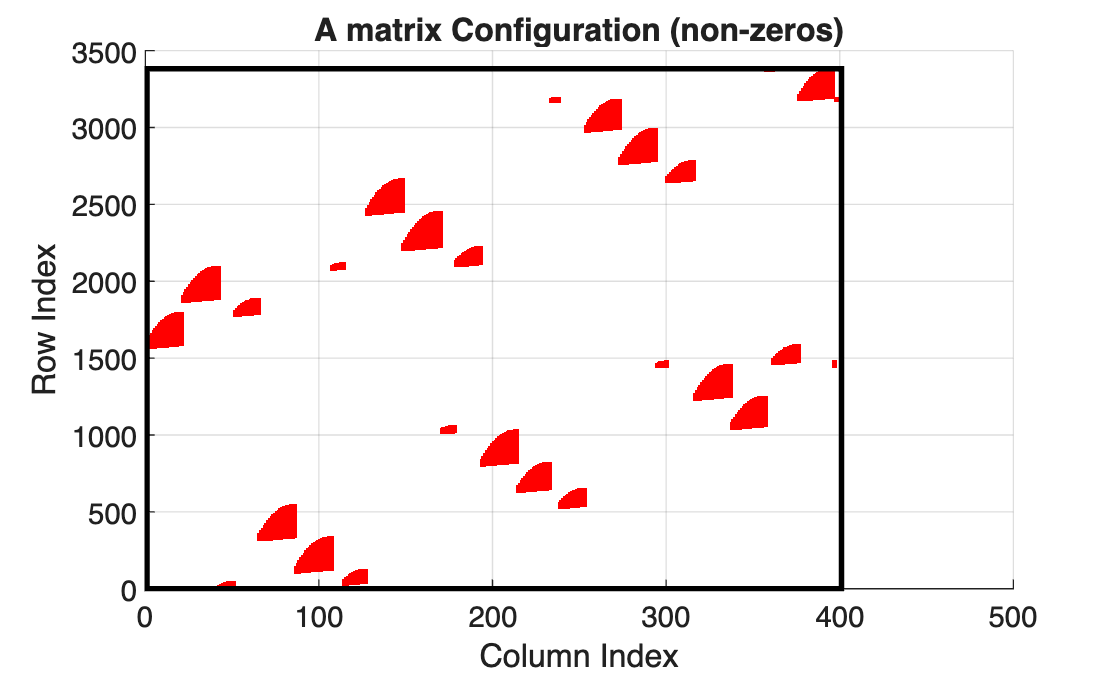

A = [];
b_mat = [];
for i = 1:p
  if isempty(E1_Si.(['sat', num2str(i)])) 
  continue;
  end

  A_i = E2_Si_x.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  A = [A;A_i];
  b_i_mat =  E2_Si_t.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  b_mat = [b_mat; b_i_mat];
end

b = ones(length(b_mat(:,1)),1) + 1/tau * b_mat * A_matrix(:,3);

[A_row, A_col] = find(A==1);
figure;
hold on
scatter(A_col,A_row,'r','.')
rectangle('Position',[1 1 max(A_col), max(A_row)], ...
          'EdgeColor','k', ...
          'LineWidth',2);
title('A matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on

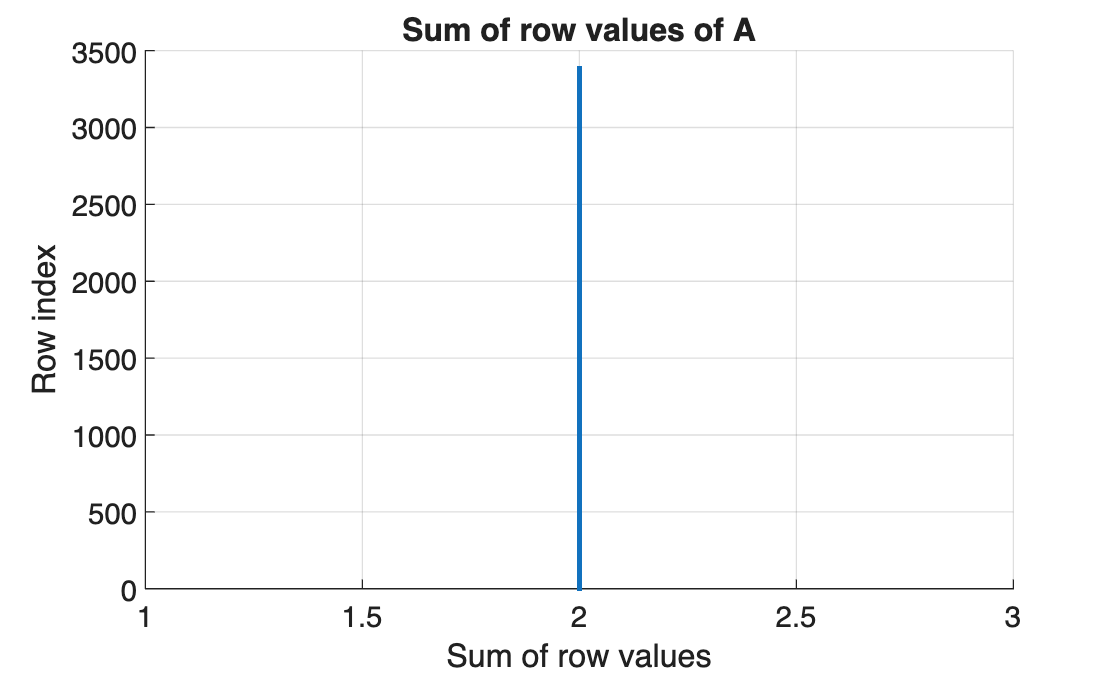



row_sum = sum(A, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of A','FontSize',12,'FontWeight','bold')

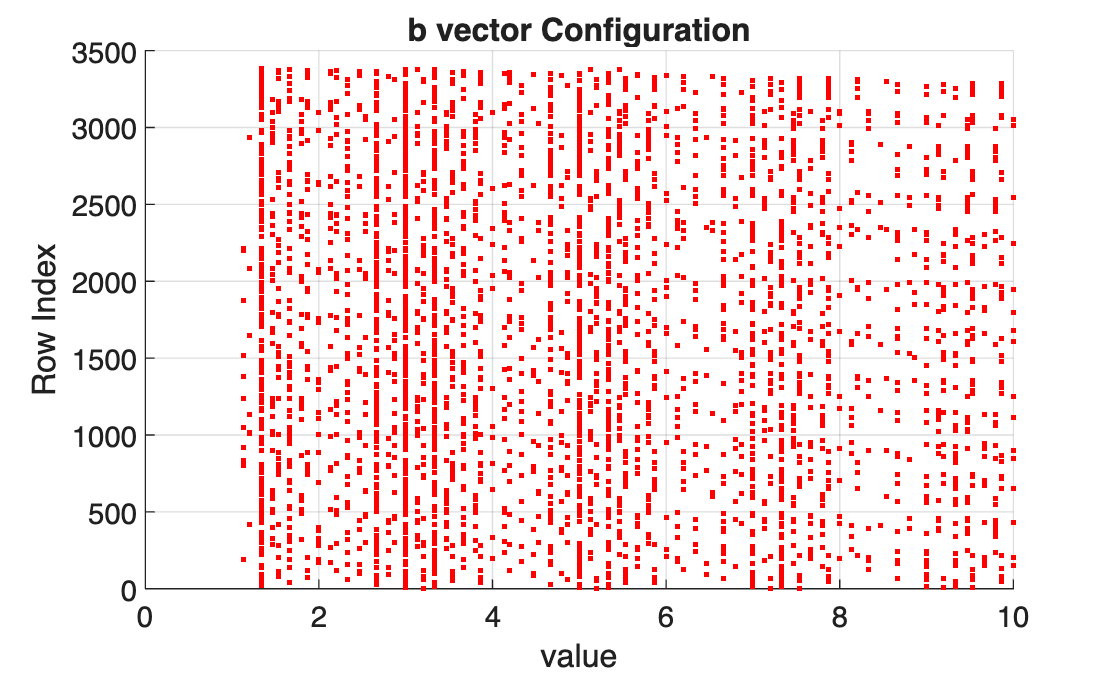



figure;
scatter(b,1:length(b),'r','.')
title('b vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
xlim([0,10])
grid on

#### 4.2 $C,d$ for $L_{\infty }$ problem

C = [];
d = [];

t = A_matrix(:,3);                  % (N×1) time vector in seconds (already prepared)
t_aug = [min(A_matrix(:,3)); t; max(A_matrix(:,3))+1];        % (N+2 × 1)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % =========================
    % Build C_j  (constant)
    % =========================
    % D_j = diag( E2t*E1 * t_aug )   (vector -> diagonal matrix)
    Dj_vec = (E2t * E1) * t_aug;           % (#rows_j × 1)
    Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec));  % sparse diag is safer

    % P = [0_{1×N}; I_{N×N}; 0_{1×N}]  -> (N+2 × N)
    N = length(t);
    P = [zeros(1,N); speye(N); zeros(1,N)];

    % C_j = D_j * (E2x*E1) * P
    Cj = Dj * (E2x * E1) * P;

    % =========================
    % Build d_j  (constant)
    % =========================
    % v = [1; 0_{N×1}; 1] - 1  = [0; -1...; 0]
    v = [1; zeros(N,1); 1];          % (N+2 × 1)

    % d_j = D_j * (E2x*E1) * v
    dj = Dj * ((E2x * E1) * v - ones(length(Dj(:,1)),1));

    % --- stack ---
    C = [C; Cj];
    d = [d; dj];
end


% [C_row, C_col] = find(C~=0);
% 
% figure;
% scatter(C_row, C_col,'r','.')
% grid on

#### 4.3 $E,f,G$ for $L_2$ Optimization problem

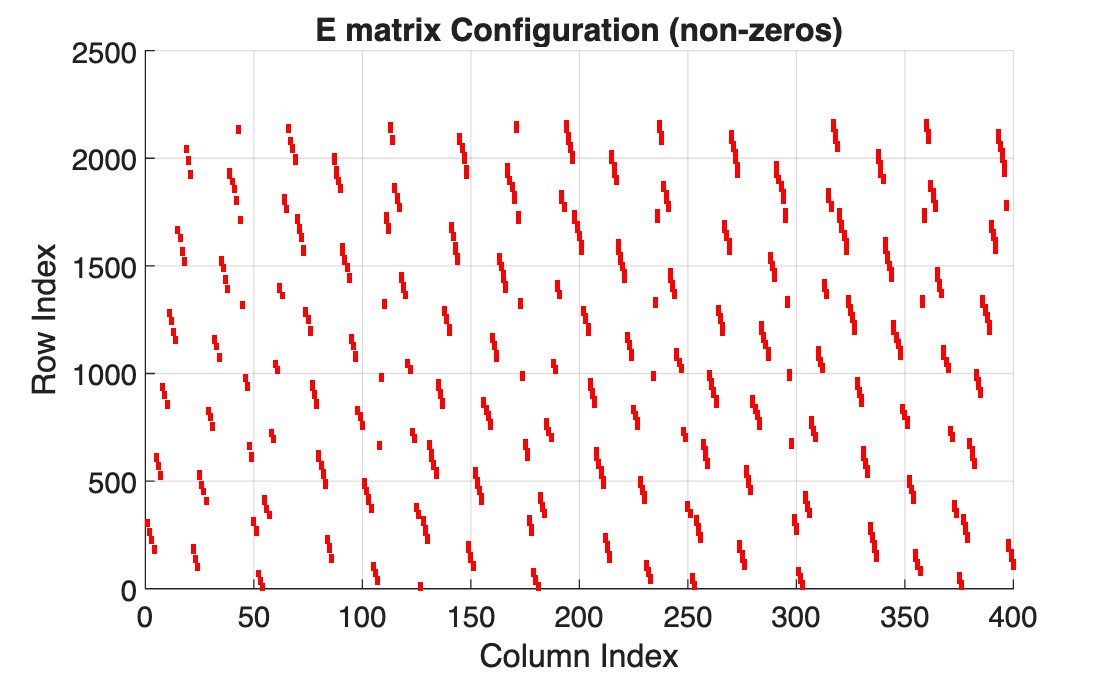

% =========================
% Build E, f, G  (2nd image)
% =========================

E_ori = [];
F = [];

t = A_matrix(:,3);                       % (N×1)
N = length(t);

t_aug = [min(t); t; max(t)+1];                % (N+2 × 1), same as your code

% P = [0_{1×N}; I_N; 0_{1×N}]  -> (N+2 × N)
P = [zeros(1,N); speye(N); zeros(1,N)];

% this is the (N+2 × 1) vector [1; 0_N; 1]
one_aug = [1; zeros(N,1); 1];

% For G, we will build the stacked matrix Bt = [E2t*E1; ...] first (optional),
% or directly build gvec = Bt*t_aug.
gvec = [];   % = Bt * t_aug  (will be stacked across j)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % Common blocks
    Sx = (E2x * E1);          % (#rows_j × (N+2))
    St = (E2t * E1);          % (#rows_j × (N+2))

    % -------------------------
    % E_j = Sx * P    (constant)
    % -------------------------
    Ej = Sx;              % (#rows_j × N)
    E_ori  = [E_ori; Ej];

    % -------------------------
    % f_j = Sx]
    % -------------------------
    Fj = Sx;        % (#rows_j × 1)
    F  = [F; Fj];

    % -------------------------
    % gvec_j = St * t_aug
    % -------------------------
    gvec_j = St * t_aug;      % (#rows_j × 1)
    gvec   = [gvec; gvec_j];
end

% Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec)); 

E = E_ori * P;
f_vector = F * one_aug;

% -------------------------
% G = gvec * gvec'
% -------------------------
% WARNING: this can be very large/dense if gvec is long.
% If you only need y'*G*y, note that y'*(gvec*gvec')*y = (gvec'*y)^2.
G = spdiags(gvec, 0, length(gvec), length(gvec));   % (M×M)


[E_one_col, E_one_row] = find(E == 1);
[E_minus_one_col, E_minus_one_row] = find(E == -1);

figure;
hold on
scatter(E_minus_one_row, E_minus_one_col,'blue','.')
scatter(E_one_row, E_one_col,'red','.')


grid on
title('E matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on

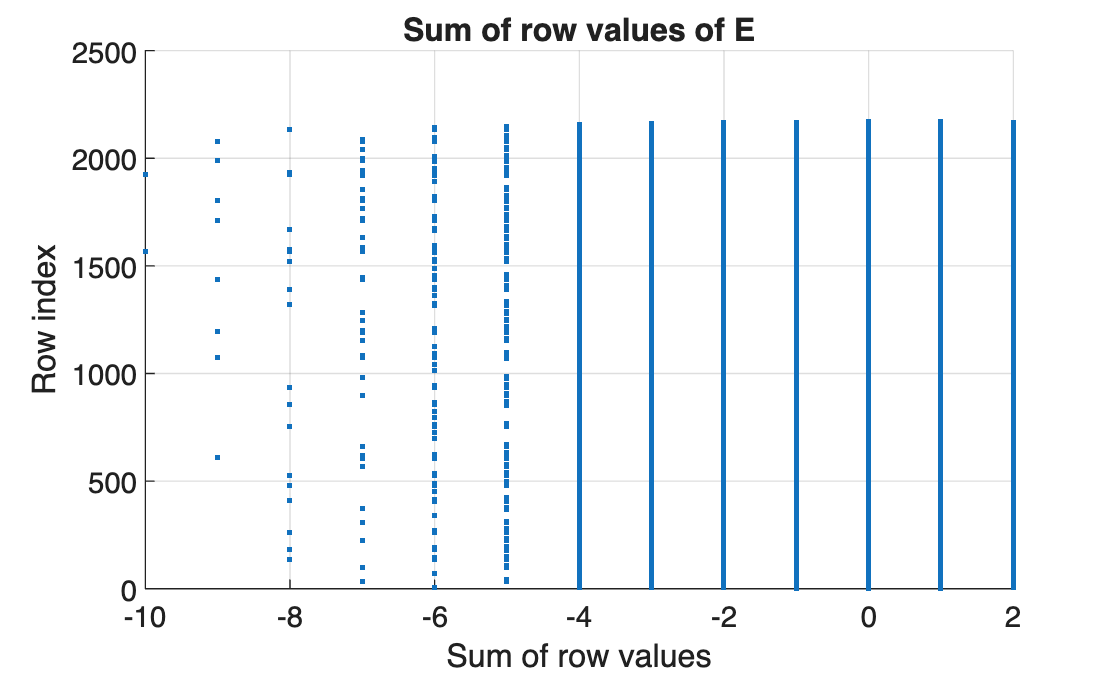

row_sum = sum(E, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of E','FontSize',12,'FontWeight','bold')

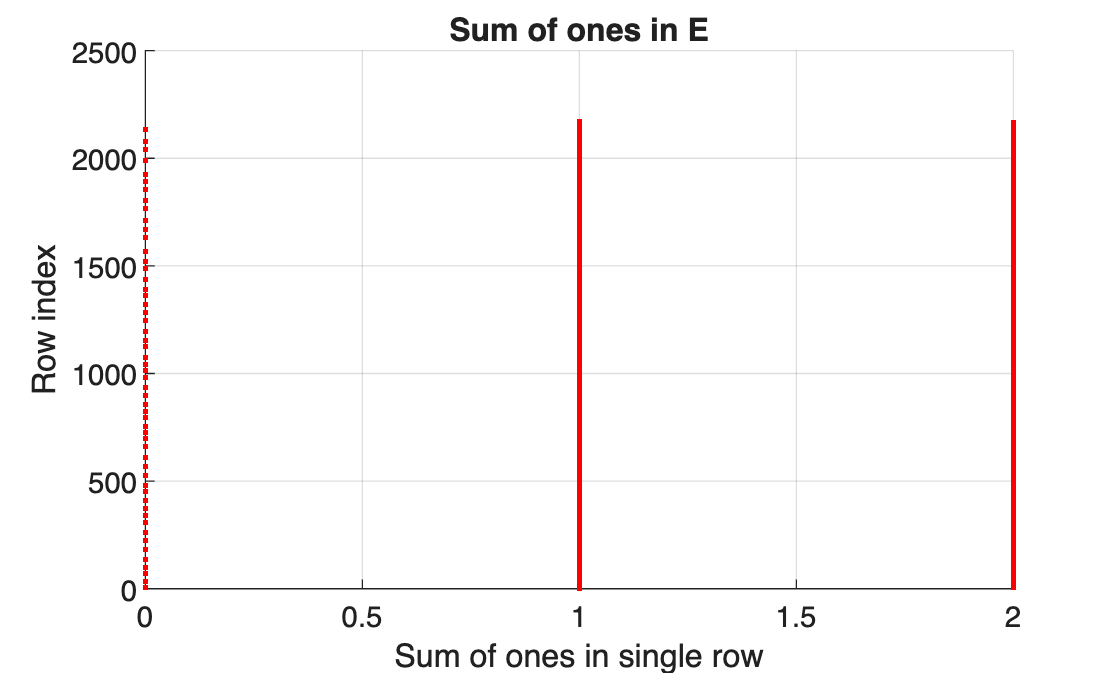



row_one_sum = sum(E == 1, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_one_sum,1:length(row_one_sum),'.','r');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of ones in single row')
title('Sum of ones in E','FontSize',12,'FontWeight','bold')

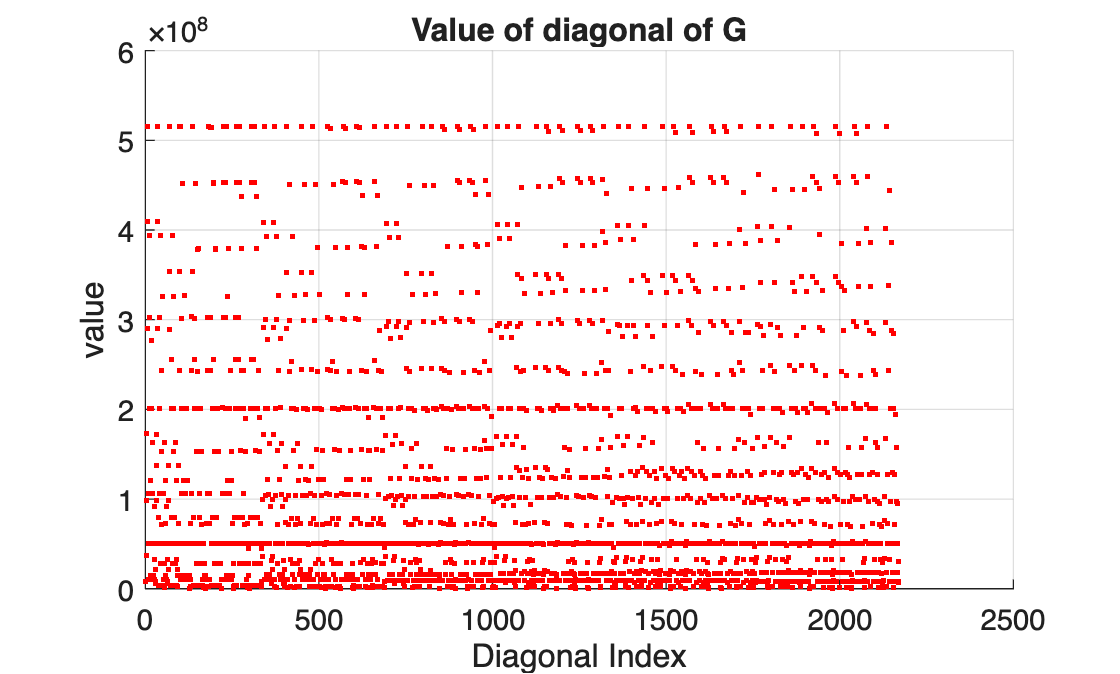


scatter(1:length(gvec),gvec.^2,'r','.')
title('Value of diagonal of G','FontSize',12,'FontWeight','bold');
ylabel('value')
xlabel('Diagonal Index')
grid on

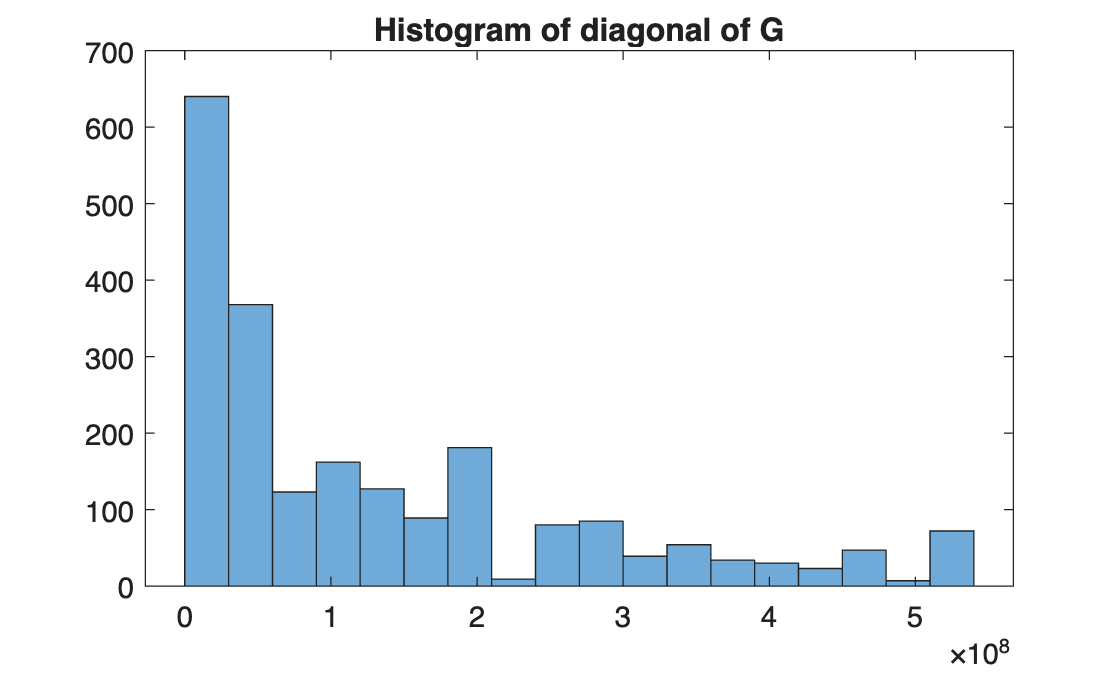


figure;
histogram(gvec.^2)
title('Histogram of diagonal of G','FontSize',12,'FontWeight','bold');

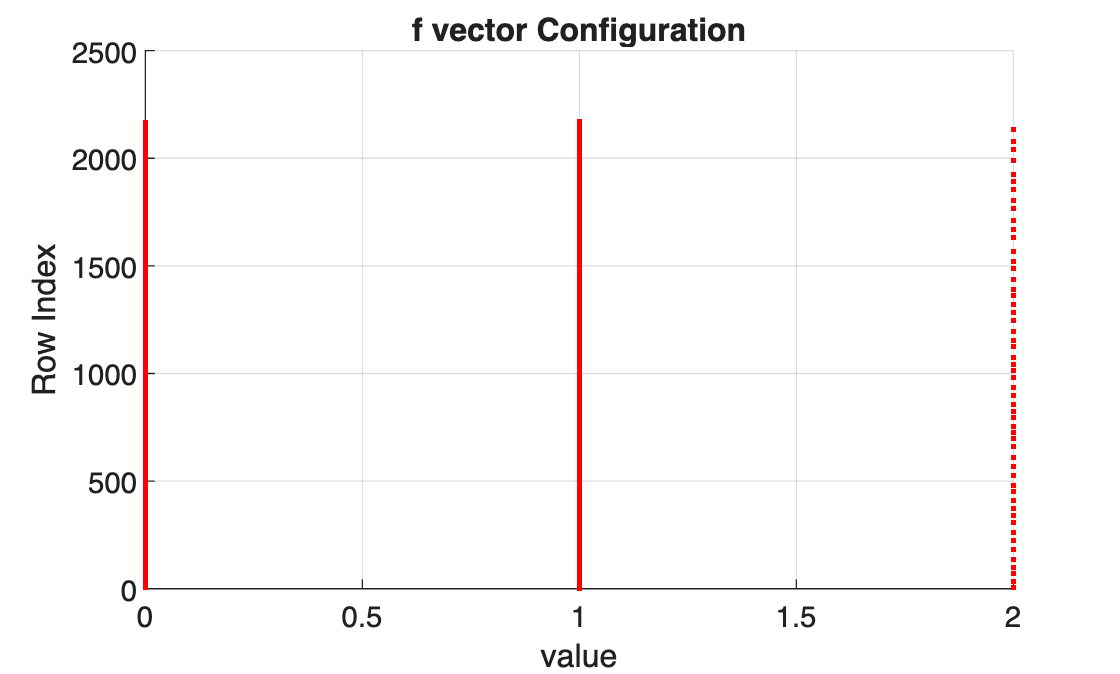


scatter(f_vector,1:length(f_vector),'r','.')
title('f vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
grid on

## 5. Optimization Problem (MILP)

L1_flag = 0;
L_infty_flag = 0;
L2_flag = 0;
L2_flag_relaxed = 0;

### 5.1. $L_1$ revisit time problem to MILP

if L1_flag == 1

%% Given: A (m×N), b (m×1), N (scalar)
% Goal: max 1^T x  s.t. A x <= b, x in {0,1}^N

% ---------- 1) Dimensions / sanity checks ----------
[m, nA] = size(A);
assert(nA == N, 'A must have N columns.');
assert(isvector(b) && length(b) == m, 'b must be m×1 to match A.');

b = b(:);                 % force column vector
Aineq = A;
bineq = b;

% ---------- 2) Convert max to min ----------
% intlinprog solves: min f'*x
f = -ones(N,1);           % minimize -sum(x) == maximize sum(x)

% ---------- 3) Binary variable settings ----------
intcon = 1:N;             % all variables are integer
lb = zeros(N,1);
ub = ones(N,1);

% (Optional) If you truly want "binary", keep intcon + bounds [0,1].
% Alternatively, you can also set intcon and bounds; that's standard.

% ---------- 4) Solve MILP ----------
% opts = optimoptions('intlinprog', ...
%     'Display','iter', ...
%     'Heuristics','advanced', ...
%     'CutGeneration','advanced');

[x_opt_L1, fval, exitflag, output] = intlinprog( ...
    f, intcon, Aineq, bineq, [], [], lb, ub);
% ---------- 5) Recover maximization objective ----------
max_onesTx = -fval;       % because f = -1
x_opt_L1 = round(x_opt_L1);     % safety: should already be integer

% ---------- 6) Quick checks ----------
viol = Aineq*x_opt_L1 - bineq;
max_viol = max(viol);

row_index_L1 = x_opt_L1 .*  A_matrix(:,4);
row_index_L1 = row_index_L1(row_index_L1 ~=0);
Original_A_L1 = T(row_index_L1,:);
A_matrix_L1 = A_matrix(x_opt_L1 == 1,:);

fprintf('Exitflag: %d\n', exitflag);
fprintf('Objective (max 1^T x): %.0f\n', max_onesTx);
fprintf('Max constraint violation: %.3e\n', max_viol);
end

### 5.2 $L_{\infty }$ revisit time problem to MILP

% Using MATLAB

% if L_infty_flag == 1
% % 
% % % Given:
% % A (m×N), b (m×1)
% % C (q×N), d (q×1)
% % N (scalar)
% 
% % ---------- sanity ----------
% [m, nA] = size(A);
% assert(nA == N, 'A must have N columns.');
% b = b(:);  assert(length(b) == m, 'b must be m×1.');
% 
% [q, nC] = size(C);
% assert(nC == N, 'C must have N columns.');
% d = d(:);  assert(length(d) == q, 'd must be q×1.');
% 
% % ---------- decision variables ----------
% % z = [x; R]  -> length N+1
% nvar = N + 1;
% 
% % Objective: min R  => f = [0...0, 1]
% f = [zeros(N,1); 1];
% 
% % Integer constraints: x binary, R continuous
% intcon = 1:N;
% 
% % Bounds
% lb = [zeros(N,1); 0];      % R >= 0 (필요 없으면 -Inf로 바꿔도 됨)
% ub = [ones(N,1);  Inf];
% 
% % ---------- Build inequalities Aineq*z <= bineq ----------
% % 1) Ax <= b  -> [A, 0] [x;R] <= b
% A1 = [A, zeros(m,1)];
% b1 = b;
% 
% % 2) Cx - R*1 <= -d  -> [C, -1] [x;R] <= -d   (각 row마다 -R)
% A2 = [C, -ones(q,1)];
% b2 = -d;
% 
% Aineq = [A1; A2];
% bineq = [b1; b2];
% 
% % (No equality constraints)
% Aeq = [];
% beq = [];
% 
% % ---------- Solve ----------
% % opts = optimoptions('intlinprog', ...
% %     'Display','iter', ...
% %     'Heuristics','advanced', ...
% %     'CutGeneration','advanced');
% 
% [z_opt, fval, exitflag, output] = intlinprog( ...
%     f, intcon, Aineq, bineq, Aeq, beq, lb, ub);
% % ---------- Parse solution ----------
% x_opt_L_inf = round(z_opt(1:N));     % binary
% R_opt = z_opt(N+1);            % optimal R
% 
% 
% row_index_L_inf = x_opt_L_inf .*  A_matrix(:,4);
% row_index_L_inf = row_index_L_inf(row_index_L_inf ~=0);
% Original_A_L_inf = T(row_index_L_inf,:);
% A_matrix_L_inf = A_matrix(x_opt_L_inf == 1,:);
% 
% 
% 
% % ---------- Feasibility check ----------
% viol1 = A*x_opt_L_inf - b;
% viol2 = C*x_opt_L_inf + d - R_opt*ones(q,1);   % should be <= 0
% fprintf('Exitflag: %d\n', exitflag);
% fprintf('R_opt: %.6f\n', R_opt);
% fprintf('max(Ax-b): %.3e\n', max(viol1));
% fprintf('max(Cx+d-R): %.3e\n', max(viol2));
% end

% Using Gurobi

if L_infty_flag == 1

%% Given:
% A (m×N), b (m×1)
% C (q×N), d (q×1)
% N (scalar)

% ---------- sanity ----------
[m, nA] = size(A);
assert(nA == N, 'A must have N columns.');
b = b(:);  assert(length(b) == m, 'b must be m×1.');

[q, nC] = size(C);
assert(nC == N, 'C must have N columns.');
d = d(:);  assert(length(d) == q, 'd must be q×1.');

% ---------- decision variables ----------
% z = [x; R]  -> length N+1
nvar = N + 1;

% ---------- Build Gurobi model ----------
model = struct();

% Constraints:
% 1) Ax <= b  -> [A, 0] z <= b
A1 = [A, sparse(m,1)];
rhs1 = b;
sense1 = repmat('<', m, 1);

% 2) Cx - R*1 <= -d -> [C, -1] z <= -d
A2 = [C, -ones(q,1)];
rhs2 = -d;
sense2 = repmat('<', q, 1);

model.A     = sparse([A1; A2]);
model.rhs   = [rhs1; rhs2];
model.sense = [sense1; sense2];

% Objective: min R => obj = [0...0, 1]
model.obj = [zeros(N,1); 1];
model.modelsense = 'min';

% Variable types: x binary, R continuous
model.vtype = [repmat('B', 1, N), 'C'];

% Bounds: 0<=x<=1, R>=0
model.lb = [zeros(N,1); 0];
model.ub = [ones(N,1);  inf];

% ---------- Solve ----------
params = struct();
params.OutputFlag = 1;   % 1: show log, 0: silent
% params.MIPGap = 1e-4;  % optional

result = gurobi(model, params);

% ---------- Parse solution ----------
if ~isfield(result, 'x') || isempty(result.x)
    error('Gurobi failed. Status: %s', result.status);
end

z_opt = result.x;

x_opt_L_inf = round(z_opt(1:N));   % binary
R_opt = z_opt(N+1);

row_index_L_inf = x_opt_L_inf .* A_matrix(:,4);
row_index_L_inf = row_index_L_inf(row_index_L_inf ~= 0);

Original_A_L_inf = T(row_index_L_inf,:);
A_matrix_L_inf   = A_matrix(x_opt_L_inf == 1,:);

% ---------- Feasibility check ----------
viol1 = A*x_opt_L_inf - b;
viol2 = C*x_opt_L_inf + d - R_opt*ones(q,1);   % should be <= 0

fprintf('Gurobi status: %s\n', result.status);
fprintf('R_opt: %.6f\n', R_opt);
fprintf('max(Ax-b): %.3e\n', max(viol1));
fprintf('max(Cx+d-R): %.3e\n', max(viol2));

end


### 5.3 $L_2$ revisit time problem to MIQP

%% ============================================================
%  L1(혹은 weighted slack) 형태:  min 1^T G^2 z
%  s.t. A x <= b, x binary
%       z >= E x + f - 1, z >= 0
%% ============================================================

if L2_flag == 1   % <- 원래 flag명을 쓰셨지만, 여기선 "L1-style" 문제라고 가정
    params = struct();
    params.OutputFlag = 1;
    params.MIPGap     = 1e-4;

    res = solve_milp_gurobi_L1(A, b, E, f_vector, gvec, params);

    x_sol = res.x_bin;
    z_sol = res.z;

    % ===== 후처리(기존 코드 스타일 유지) =====
    x_opt_L2 = x_sol;   % binary
    row_index_L2 = x_opt_L2 .* A_matrix(:,4);
    row_index_L2 = row_index_L2(row_index_L2 ~= 0);

    Original_A_L2 = T(row_index_L2,:);
    A_matrix_L2   = A_matrix(x_opt_L2 == 1,:);

end

Set parameter Username
Set parameter LicenseID to value 2767696
Academic license - for non-commercial use only - expires 2027-01-20
Gurobi Optimizer version 13.0.0 build v13.0.0rc1 (mac64[arm] - Darwin 24.6.0 24G90)

CPU model: Apple M3
Thread count: 8 physical cores, 8 logical processors, using up to 8 threads

Optimize a model with 5551 rows, 2570 columns and 17932 nonzeros (Min)
Model fingerprint: 0x1da254e6
Model has 2169 linear objective coefficients
Variable types: 2170 continuous, 400 integer (400 binary)
Coefficient statistics:
  Matrix range     [1e+00, 1e+00]
  Objective range  [1e+00, 5e+08]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 4e+02]
Found heuristic solution: objective 2.783302e+10
Presolve removed 3325 rows and 108 columns
Presolve time: 0.40s
Presolved: 2226 rows, 2462 columns, 11410 nonzeros
Variable types: 0 continuous, 2462 integer (2462 binary)

Root relaxation: objective 3.468476e+07, 548 iterations, 0.00 seconds (0.01 work units)

    Nodes  



function result = solve_milp_gurobi_L1(A, b, E, f, gvec, params)
% Solve MILP with Gurobi (MATLAB interface):
%
%   min    1^T * (G^2) * z   = sum_i (g_i^2) * z_i
%   s.t.   A x <= b,              x in {0,1}^N
%          z >= E x + f - 1
%          z >= 0
%
% Decision variables: w = [x; z]
%   x: N binary
%   z: M continuous (slack-like)

    if nargin < 6 || isempty(params)
        params = struct();
    end

    % ----- sizes -----
    N = size(A, 2);
    M = size(E, 1);

    % ----- checks -----
    assert(size(A,1) == numel(b), 'A and b size mismatch');
    assert(size(E,2) == N, 'E must be MxN');
    assert(numel(f) == M, 'f must be length M');
    assert(numel(gvec) == M, 'gvec must be length M');

    b = b(:);
    f = f(:);
    g = gvec(:);

    % =========================
    % Constraints
    % =========================
    % (i) A x <= b
    A1     = [A, sparse(size(A,1), M)];
    rhs1   = b;
    sense1 = repmat('<', size(A,1), 1);

    % (ii) z >= E x + f - 1
    %      <=>  (-E)x + I*z >= (f - 1)
    A2     = [-E, speye(M)];
    rhs2   = (f - 1);
    sense2 = repmat('>', M, 1);

    model = struct();
    model.A     = sparse([A1; A2]);
    model.rhs   = [rhs1; rhs2];
    model.sense = [sense1; sense2];

    % =========================
    % Objective: sum (g.^2 .* z)
    % =========================
    obj = zeros(N+M,1);
    obj(N+1:N+M) = (g.^2);         % 1^T G^2 z
    model.obj = obj;
    model.modelsense = 'min';

    % =========================
    % Variable types & bounds
    % =========================
    model.vtype = [repmat('B', 1, N), repmat('C', 1, M)];

    % bounds:
    % x: binary -> [0,1] automatically ok
    % z: >=0 (upper bound can be Inf)
    model.lb = [zeros(N,1); zeros(M,1)];
    model.ub = [ones(N,1);  inf(M,1)];

    % =========================
    % Params defaults
    % =========================
    if ~isfield(params, 'OutputFlag'); params.OutputFlag = 1; end
    if ~isfield(params, 'MIPGap');     params.MIPGap     = 1e-4; end

    % ----- solve -----
    out = gurobi(model, params);

    % ----- unpack -----
    result = out;  % 원본 결과도 유지
    if isfield(out, 'x') && ~isempty(out.x)
        w = out.x;
        result.x_bin = w(1:N);
        result.z     = w(N+1:N+M);

        % objective value (linear)
        result.obj = (g.^2)' * result.z;
    end
end



### 5.4 $L_2$ revisit time problem to Relaxed QP

if L2_flag_relaxed == 1
params = struct();
params.OutputFlag = 1;
params.MIPGap = 1e-4;
% params.NonConvex = 2;  % G가 PSD가 아닐 수도 있으면 켜세요.

res = solve_qp_gurobi(A, b, E, f_vector, gvec, params);
end

function result = solve_qp_gurobi(A, b, E, f, gvec, params)
% Solve the relaxed problem as a convex QP with Gurobi (MATLAB interface):
%
%   min    || gvec .* (y - 1) ||_2   (implemented as squared norm)
%   s.t.   A x <= b
%          y >= E x + f
%          0 <= x <= 1
%          0 <= y <= 2
%
% Decision variables: z = [x; y]
%
% Objective in quadratic form:
%   (y-1)' diag(g.^2) (y-1) = y' D y - 2 (g.^2)' y + const
% Gurobi uses: (1/2) z'Qz + obj'z

    if nargin < 6 || isempty(params)
        params = struct();
    end

    % ----- sizes -----
    N = size(A, 2);
    M = size(E, 1);

    % ----- checks -----
    assert(size(A,1) == numel(b), 'A and b size mismatch');
    assert(size(E,2) == N, 'E must be MxN');
    assert(numel(f) == M, 'f must be length M');
    assert(numel(gvec) == M, 'gvec must be length M');

    b = b(:);
    f = f(:);
    g = gvec(:);

    % =========================
    % Constraints
    % =========================
    % (i) A x <= b
    A1     = [A, sparse(size(A,1), M)];
    rhs1   = b;
    sense1 = repmat('<', size(A,1), 1);

    % (ii) y >= E x + f  <=>  (-E)x + I*y >= f
    A2     = [-E, speye(M)];
    rhs2   = f;
    sense2 = repmat('>', M, 1);

    model = struct();
    model.A     = sparse([A1; A2]);
    model.rhs   = [rhs1; rhs2];
    model.sense = [sense1; sense2];

    % =========================
    % Objective (squared norm)
    % =========================
    % D = diag(g.^2)
    D = spdiags(g.^2, 0, M, M);

    % Build Q for z=[x;y]
    Q = sparse(N+M, N+M);
    Q(N+1:N+M, N+1:N+M) = 2 * D;     % so (1/2)*y'(2D)y = y'Dy
    model.Q = Q;

    % Linear term: -2*(g.^2)' y
    obj = zeros(N+M,1);
    obj(N+1:N+M) = -2*(g.^2);
    model.obj = obj;

    model.modelsense = 'min';

    % =========================
    % Variable types & bounds
    % =========================
    % Relax x to continuous: both x and y are continuous
    model.vtype = repmat('C', 1, N+M);

    % Bounds
    model.lb = [zeros(N,1); ones(M,1)];
    model.ub = [ones(N,1);  2*ones(M,1)];

    % ---- (옵션) y 하한을 1로 두고 싶으면 아래 두 줄로 교체 ----
    % model.lb = [zeros(N,1); ones(M,1)];
    % model.ub = [ones(N,1);  2*ones(M,1)];

    % =========================
    % Params defaults
    % =========================
    if ~isfield(params, 'OutputFlag'); params.OutputFlag = 1; end

    % Convex QP이면 NonConvex 필요 없음.
    % 혹시 g에 NaN/Inf가 있거나 Q가 비정상인 경우만 점검.

    % ----- solve -----
    result = gurobi(model, params);

    % ----- unpack -----
    if isfield(result, 'x') && ~isempty(result.x)
        z = result.x;
        result.x_relaxed = z(1:N);
        result.y         = z(N+1:N+M);

        diff = result.y - 1;
        result.obj_sq = sum((g .* diff).^2);
        result.obj    = sqrt(max(result.obj_sq, 0));
    end
end

### 6.0 Original Revisit Time Status Result

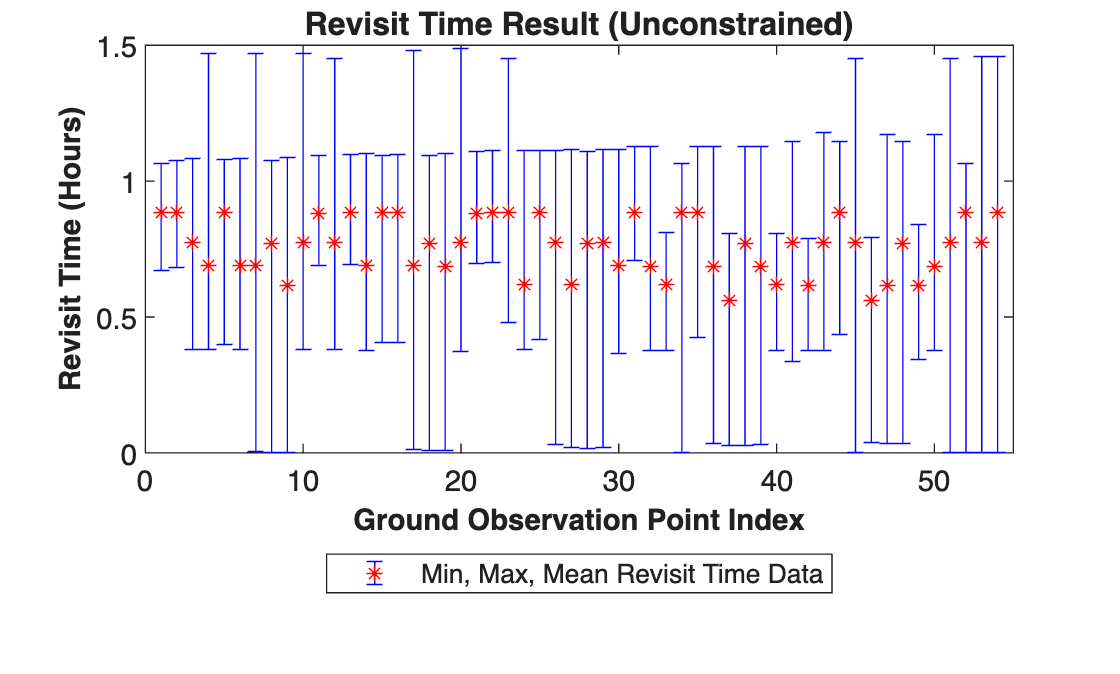

t_start = t0 + seconds(min(A_matrix(:,3)));
t_end = t0 + seconds(max(A_matrix(:,3))+1);


% Extract Ground Point Tables
  T = Original_A;

    % Source 열에서 고유 값 추출
    sources = unique(T.Source);

    % Revisit Time Matrix (Min / Max / Mean) 생성
    Revisit_Matrix = zeros(length(sources),3);
    revisit_time_vector_combined = [];

    % 각각의 Source 별로 테이블을 분리하여 저장
    for i = 1:length(sources)
        src = sources{i};

        % Source 값이 같은 행들만 추출
        subTable = T(strcmp(T.Source, src), :);
        subTable_sorted = sortrows(subTable,4,"ascend");


        % 동적으로 변수 생성 (예: Ground_Point_1_Table)
        varName = sprintf('%s_Table', src);
        % assignin('base', varName, subTable_sorted);
        contact_tables.(sprintf('%s_Table', src)) = subTable_sorted;

        % 기존 row에 start 및 endtime 추가
        row0 = subTable_sorted(1,:);
        
        % -------------------------
        % 윗줄 (t_start)
        % -------------------------
        row_top = row0;
        row_top.IntervalNumber = NaN;      % 필요 없으면 NaN
        row_top.StartTime = t_start;
        row_top.EndTime   = t_start;
        row_top.Duration  = 0;
        row_top.StartOrbit = 0;
        row_top.EndOrbit   = 0;
        
        % -------------------------
        % 아랫줄 (t_end)
        % -------------------------
        row_bottom = row0;
        row_bottom.IntervalNumber = NaN;
        row_bottom.StartTime = t_end;
        row_bottom.EndTime   = t_end;
        row_bottom.Duration  = 0;
        row_bottom.StartOrbit = 0;
        row_bottom.EndOrbit   = 0;
        
        % -------------------------
        % 위 + 기존 + 아래 결합
        % -------------------------
        subTable_sorted = [row_top; subTable_sorted; row_bottom];

        % Initialize Revisit Time Vector
        revisit_time_vector = zeros(height(subTable_sorted)-1,1);

        for revisit_time_index = 1:length(revisit_time_vector)
            revisit_time_vector(revisit_time_index) = seconds(table2array(subTable_sorted(revisit_time_index+1,4))-table2array(subTable_sorted(revisit_time_index,5)));

            if revisit_time_vector(revisit_time_index) < 0
               revisit_time_vector(revisit_time_index) = 0;
            end
        revisit_vectors.(sprintf('%s_revisit_time_vec', src)) = revisit_time_vector;
        end

        % 생성된 Revisit Time Vector의 Min / Max / Mean 값을 Revisit Time Matrix에 저장
        Revisit_Matrix(i,1) = min(revisit_time_vector);
        Revisit_Matrix(i,2) = max(revisit_time_vector);

        % 재방문 주기의 평균을 구할때는 재방문 주기가 0인 데이터 포인트를 모두 제외하였음
        revisit_time_vector = revisit_time_vector(revisit_time_vector~=0);

        Revisit_Matrix(i,3) = mean(revisit_time_vector);
        revisit_time_vector_combined = [revisit_time_vector_combined;revisit_time_vector];
       revisit_time_vector_info.(['source' num2str(i)]) = revisit_time_vector;
    end

    % Revisit Time Matrix의 값을 그래프로 출력
    x = 1:length(Revisit_Matrix(:,1));
    min_value = (Revisit_Matrix(:,1))/3600;
    max_value = (Revisit_Matrix(:,2))/3600;
    mean_value = (Revisit_Matrix(:,3))/3600;
    output_data = [mean_value, min_value, max_value];

    figure;
    errorbar(x, mean_value, mean_value-min_value, max_value-mean_value,'*','LineStyle','none','color','b','MarkerEdgeColor','r')
    t = title('Revisit Time Result (Unconstrained)','FontSize',12,'FontWeight','bold');
    xlabel('Ground Observation Point Index','FontSize',11,'FontWeight','bold')
    ylabel('Revisit Time (Hours)','FontSize',11,'FontWeight','bold')
    legend('Min, Max, Mean Revisit Time Data','Location','southoutside')
    xlim([-1, length(Revisit_Matrix(:,1))]+1)  

### 6.1  L1 Revisit Time Status Result

if L1_flag == 1
    
A_matrix_result = A_matrix;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_original = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_matrix_original(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end

    
A_matrix_result = A_matrix_L1;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_L1 = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);     
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end


      cadence_matrix_L1(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end

figure;
hold on
scatter(cadence_matrix_original(:,1),cadence_matrix_original(:,3),'o','red')
scatter(cadence_matrix_L1(:,1),cadence_matrix_L1(:,3),'*','blue')
title('Satellite Operation Minimum  Cadence for L1','FontSize',12,'FontWeight','bold')
xlabel('Satellite No.')
ylabel('Operation Cadence (sec)')
legend('Unconstrained','L1')
grid on


% Extract Ground Point Tables
  T = Original_A_L1;

    % Source 열에서 고유 값 추출
    sources = unique(T.Source);

    % Revisit Time Matrix (Min / Max / Mean) 생성
    Revisit_Matrix = zeros(length(sources),3);
    revisit_time_vector_combined = [];

    % 각각의 Source 별로 테이블을 분리하여 저장
    for i = 1:length(sources)
        src = sources{i};

        % Source 값이 같은 행들만 추출
        subTable = T(strcmp(T.Source, src), :);
        subTable_sorted = sortrows(subTable,4,"ascend");


        % 동적으로 변수 생성 (예: Ground_Point_1_Table)
        varName = sprintf('%s_Table', src);
        % assignin('base', varName, subTable_sorted);
        contact_tables.(sprintf('%s_Table', src)) = subTable_sorted;

        % 기존 row에 start 및 endtime 추가
        row0 = subTable_sorted(1,:);
        
        % -------------------------
        % 윗줄 (t_start)
        % -------------------------
        row_top = row0;
        row_top.IntervalNumber = NaN;      % 필요 없으면 NaN
        row_top.StartTime = t_start;
        row_top.EndTime   = t_start;
        row_top.Duration  = 0;
        row_top.StartOrbit = 0;
        row_top.EndOrbit   = 0;
        
        % -------------------------
        % 아랫줄 (t_end)
        % -------------------------
        row_bottom = row0;
        row_bottom.IntervalNumber = NaN;
        row_bottom.StartTime = t_end;
        row_bottom.EndTime   = t_end;
        row_bottom.Duration  = 0;
        row_bottom.StartOrbit = 0;
        row_bottom.EndOrbit   = 0;
        
        % -------------------------
        % 위 + 기존 + 아래 결합
        % -------------------------
        subTable_sorted = [row_top; subTable_sorted; row_bottom];

        % Initialize Revisit Time Vector
        revisit_time_vector = zeros(height(subTable_sorted)-1,1);

        for revisit_time_index = 1:length(revisit_time_vector)
            revisit_time_vector(revisit_time_index) = seconds(table2array(subTable_sorted(revisit_time_index+1,4))-table2array(subTable_sorted(revisit_time_index,5)));

            if revisit_time_vector(revisit_time_index) < 0
               revisit_time_vector(revisit_time_index) = 0;
            end
        revisit_vectors.(sprintf('%s_revisit_time_vec', src)) = revisit_time_vector;
        end

        % 생성된 Revisit Time Vector의 Min / Max / Mean 값을 Revisit Time Matrix에 저장
        Revisit_Matrix(i,1) = min(revisit_time_vector);
        Revisit_Matrix(i,2) = max(revisit_time_vector);

        % 재방문 주기의 평균을 구할때는 재방문 주기가 0인 데이터 포인트를 모두 제외하였음
        revisit_time_vector = revisit_time_vector(revisit_time_vector~=0);

        Revisit_Matrix(i,3) = mean(revisit_time_vector);
        revisit_time_vector_combined = [revisit_time_vector_combined;revisit_time_vector];
       revisit_time_vector_info.(['source' num2str(i)]) = revisit_time_vector;
    end

    % Revisit Time Matrix의 값을 그래프로 출력
    x = 1:length(Revisit_Matrix(:,1));
    min_value = (Revisit_Matrix(:,1))/3600;
    max_value = (Revisit_Matrix(:,2))/3600;
    mean_value = (Revisit_Matrix(:,3))/3600;
    output_data = [mean_value, min_value, max_value];

    figure;
    errorbar(x, mean_value, mean_value-min_value, max_value-mean_value,'*','LineStyle','none','color','b','MarkerEdgeColor','r')
    t = title('Revisit Time Result (L1)','FontSize',12,'FontWeight','bold');
    xlabel('Ground Observation Point Index','FontSize',11,'FontWeight','bold')
    ylabel('Revisit Time (Hours)','FontSize',11,'FontWeight','bold')
    legend('Min, Max, Mean Revisit Time Data','Location','southoutside')
    xlim([-1, length(Revisit_Matrix(:,1))]+1)  
end

### 6.2  L_infty Revisit Time Status Result

if L_infty_flag == 1

A_matrix_result = A_matrix;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_original = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_matrix_original(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end

    
A_matrix_result = A_matrix_L_inf;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_L_inf = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);     
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      cadence_matrix_L_inf(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end
    

cadence_matrix_L_inf = cadence_matrix_L_inf(cadence_matrix_L_inf(:,3)~=0,:);


figure;
hold on
scatter(cadence_matrix_original(:,1),cadence_matrix_original(:,3),'o','red')
scatter(cadence_matrix_L_inf(:,1),cadence_matrix_L_inf(:,3),'*','blue')
title('Satellite Operation Minimum Cadence for L infty','FontSize',12,'FontWeight','bold')
legend('Unconstrained','L infty')
xlabel('Satellite No.')
ylabel('Operation Cadence (sec)')
grid on



 % Extract Ground Point Tables
  T = Original_A_L_inf;

    % Source 열에서 고유 값 추출
    sources = unique(T.Source);

    % Revisit Time Matrix (Min / Max / Mean) 생성
    Revisit_Matrix = zeros(length(sources),3);
    revisit_time_vector_combined = [];

    % 각각의 Source 별로 테이블을 분리하여 저장
    for i = 1:length(sources)
        src = sources{i};

        % Source 값이 같은 행들만 추출
        subTable = T(strcmp(T.Source, src), :);
        subTable_sorted = sortrows(subTable,4,"ascend");


        % 동적으로 변수 생성 (예: Ground_Point_1_Table)
        varName = sprintf('%s_Table', src);
        % assignin('base', varName, subTable_sorted);
        contact_tables.(sprintf('%s_Table', src)) = subTable_sorted;

        % 기존 row에 start 및 endtime 추가
        row0 = subTable_sorted(1,:);
        
        % -------------------------
        % 윗줄 (t_start)
        % -------------------------
        row_top = row0;
        row_top.IntervalNumber = NaN;      % 필요 없으면 NaN
        row_top.StartTime = t_start;
        row_top.EndTime   = t_start;
        row_top.Duration  = 0;
        row_top.StartOrbit = 0;
        row_top.EndOrbit   = 0;
        
        % -------------------------
        % 아랫줄 (t_end)
        % -------------------------
        row_bottom = row0;
        row_bottom.IntervalNumber = NaN;
        row_bottom.StartTime = t_end;
        row_bottom.EndTime   = t_end;
        row_bottom.Duration  = 0;
        row_bottom.StartOrbit = 0;
        row_bottom.EndOrbit   = 0;
        
        % -------------------------
        % 위 + 기존 + 아래 결합
        % -------------------------
        subTable_sorted = [row_top; subTable_sorted; row_bottom];

        % Initialize Revisit Time Vector
        revisit_time_vector = zeros(height(subTable_sorted)-1,1);

        for revisit_time_index = 1:length(revisit_time_vector)
            revisit_time_vector(revisit_time_index) = seconds(table2array(subTable_sorted(revisit_time_index+1,4))-table2array(subTable_sorted(revisit_time_index,5)));

            if revisit_time_vector(revisit_time_index) < 0
               revisit_time_vector(revisit_time_index) = 0;
            end
        revisit_vectors.(sprintf('%s_revisit_time_vec', src)) = revisit_time_vector;
        end

        % 생성된 Revisit Time Vector의 Min / Max / Mean 값을 Revisit Time Matrix에 저장
        Revisit_Matrix(i,1) = min(revisit_time_vector);
        Revisit_Matrix(i,2) = max(revisit_time_vector);

        % 재방문 주기의 평균을 구할때는 재방문 주기가 0인 데이터 포인트를 모두 제외하였음
        revisit_time_vector = revisit_time_vector(revisit_time_vector~=0);

        Revisit_Matrix(i,3) = mean(revisit_time_vector);
        revisit_time_vector_combined = [revisit_time_vector_combined;revisit_time_vector];
       revisit_time_vector_info.(['source' num2str(i)]) = revisit_time_vector;
    end

    % Revisit Time Matrix의 값을 그래프로 출력
    x = 1:length(Revisit_Matrix(:,1));
    min_value = (Revisit_Matrix(:,1))/3600;
    max_value = (Revisit_Matrix(:,2))/3600;
    mean_value = (Revisit_Matrix(:,3))/3600;
    output_data = [mean_value, min_value, max_value];

    figure;
    errorbar(x, mean_value, mean_value-min_value, max_value-mean_value,'*','LineStyle','none','color','b','MarkerEdgeColor','r')
    t = title('Revisit Time Result (L infty)','FontSize',12,'FontWeight','bold');
    xlabel('Ground Observation Point Index','FontSize',11,'FontWeight','bold')
    ylabel('Revisit Time (Hours)','FontSize',11,'FontWeight','bold')
    legend('Min, Max, Mean Revisit Time Data','Location','southoutside')
    xlim([-1, length(Revisit_Matrix(:,1))]+1)
end

### 6.2  L2 Revisit Time Status Result

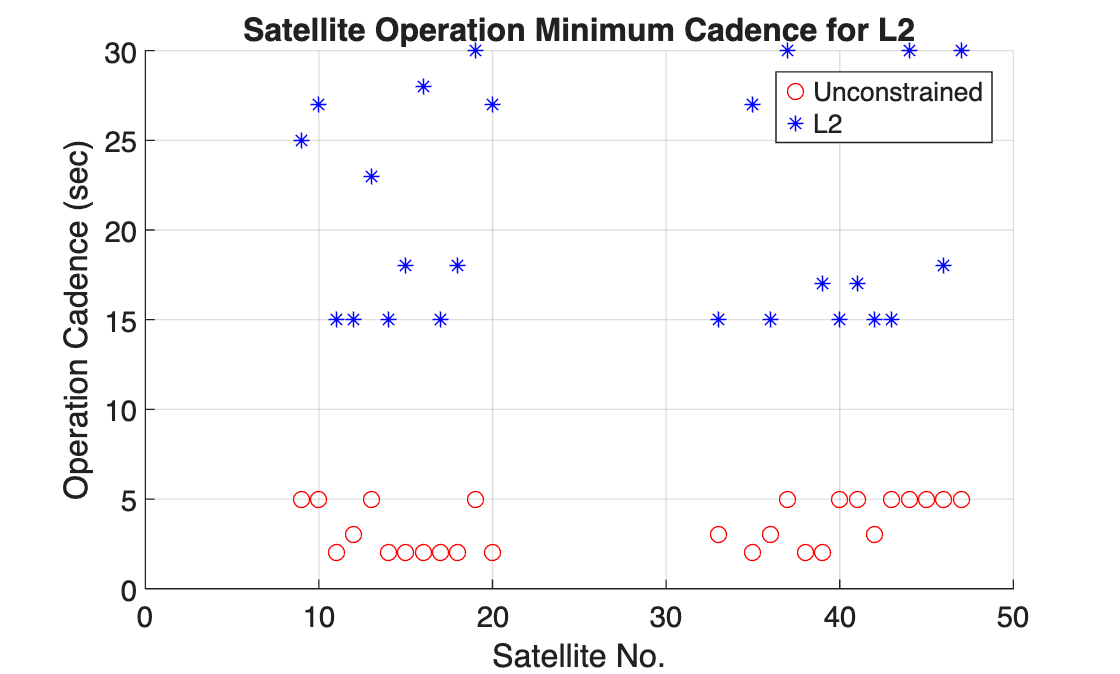

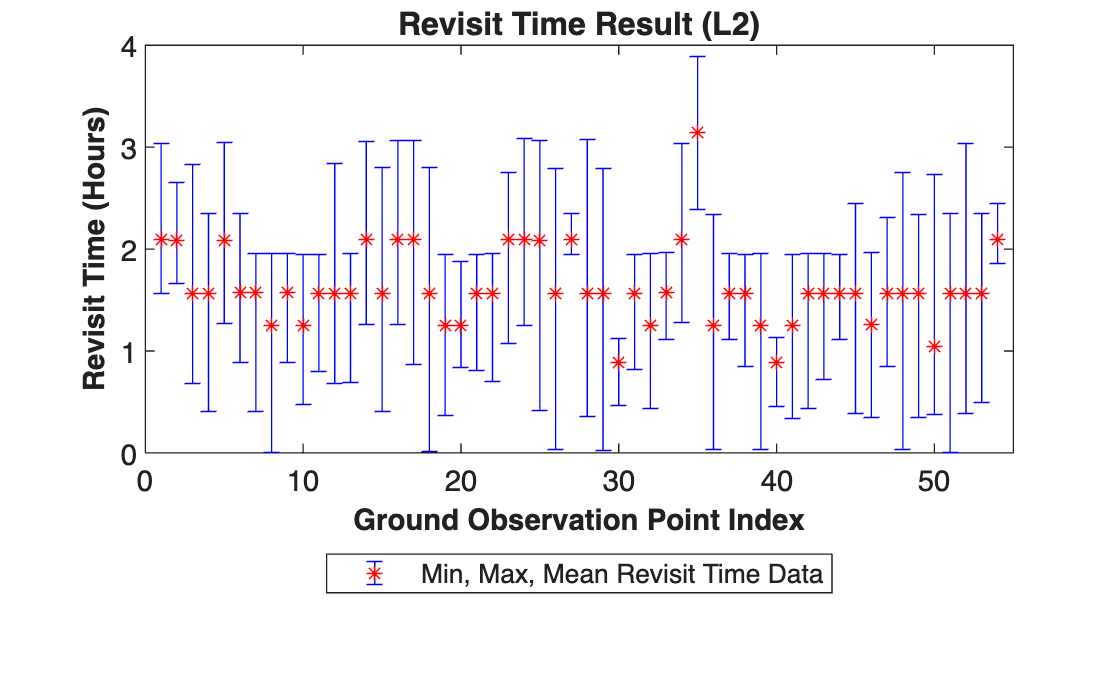

if L2_flag == 1

A_matrix_result = A_matrix;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_original = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_matrix_original(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end

    
A_matrix_result = A_matrix_L2;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_L2 = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);     
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      cadence_matrix_L2(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end
    

cadence_matrix_L2 = cadence_matrix_L2(cadence_matrix_L2(:,3)~=0,:);


figure;
hold on
scatter(cadence_matrix_original(:,1),cadence_matrix_original(:,3),'o','red')
scatter(cadence_matrix_L2(:,1),cadence_matrix_L2(:,3),'*','blue')
title('Satellite Operation Minimum Cadence for L2','FontSize',12,'FontWeight','bold')
legend('Unconstrained','L2')
xlabel('Satellite No.')
ylabel('Operation Cadence (sec)')
grid on

 % Extract Ground Point Tables
  T = Original_A_L2;

    % Source 열에서 고유 값 추출
    sources = unique(T.Source);

    % Revisit Time Matrix (Min / Max / Mean) 생성
    Revisit_Matrix = zeros(length(sources),3);
    revisit_time_vector_combined = [];

    % 각각의 Source 별로 테이블을 분리하여 저장
    for i = 1:length(sources)
        src = sources{i};

        % Source 값이 같은 행들만 추출
        subTable = T(strcmp(T.Source, src), :);
        subTable_sorted = sortrows(subTable,4,"ascend");


        % 동적으로 변수 생성 (예: Ground_Point_1_Table)
        varName = sprintf('%s_Table', src);
        % assignin('base', varName, subTable_sorted);
        contact_tables.(sprintf('%s_Table', src)) = subTable_sorted;

        % 기존 row에 start 및 endtime 추가
        row0 = subTable_sorted(1,:);
        
        % -------------------------
        % 윗줄 (t_start)
        % -------------------------
        row_top = row0;
        row_top.IntervalNumber = NaN;      % 필요 없으면 NaN
        row_top.StartTime = t_start;
        row_top.EndTime   = t_start;
        row_top.Duration  = 0;
        row_top.StartOrbit = 0;
        row_top.EndOrbit   = 0;
        
        % -------------------------
        % 아랫줄 (t_end)
        % -------------------------
        row_bottom = row0;
        row_bottom.IntervalNumber = NaN;
        row_bottom.StartTime = t_end;
        row_bottom.EndTime   = t_end;
        row_bottom.Duration  = 0;
        row_bottom.StartOrbit = 0;
        row_bottom.EndOrbit   = 0;
        
        % -------------------------
        % 위 + 기존 + 아래 결합
        % -------------------------
        subTable_sorted = [row_top; subTable_sorted; row_bottom];

        % Initialize Revisit Time Vector
        revisit_time_vector = zeros(height(subTable_sorted)-1,1);

        for revisit_time_index = 1:length(revisit_time_vector)
            revisit_time_vector(revisit_time_index) = seconds(table2array(subTable_sorted(revisit_time_index+1,4))-table2array(subTable_sorted(revisit_time_index,5)));

            if revisit_time_vector(revisit_time_index) < 0
               revisit_time_vector(revisit_time_index) = 0;
            end
        revisit_vectors.(sprintf('%s_revisit_time_vec', src)) = revisit_time_vector;
        end

        % 생성된 Revisit Time Vector의 Min / Max / Mean 값을 Revisit Time Matrix에 저장
        Revisit_Matrix(i,1) = min(revisit_time_vector);
        Revisit_Matrix(i,2) = max(revisit_time_vector);

        % 재방문 주기의 평균을 구할때는 재방문 주기가 0인 데이터 포인트를 모두 제외하였음
        revisit_time_vector = revisit_time_vector(revisit_time_vector~=0);

        Revisit_Matrix(i,3) = mean(revisit_time_vector);
        revisit_time_vector_combined = [revisit_time_vector_combined;revisit_time_vector];
       revisit_time_vector_info.(['source' num2str(i)]) = revisit_time_vector;
    end

    % Revisit Time Matrix의 값을 그래프로 출력
    x = 1:length(Revisit_Matrix(:,1));
    min_value = (Revisit_Matrix(:,1))/3600;
    max_value = (Revisit_Matrix(:,2))/3600;
    mean_value = (Revisit_Matrix(:,3))/3600;
    output_data = [mean_value, min_value, max_value];

    figure;
    errorbar(x, mean_value, mean_value-min_value, max_value-mean_value,'*','LineStyle','none','color','b','MarkerEdgeColor','r')
    t = title('Revisit Time Result (L2)','FontSize',12,'FontWeight','bold');
    xlabel('Ground Observation Point Index','FontSize',11,'FontWeight','bold')
    ylabel('Revisit Time (Hours)','FontSize',11,'FontWeight','bold')
    legend('Min, Max, Mean Revisit Time Data','Location','southoutside')
    xlim([-1, length(Revisit_Matrix(:,1))]+1)
end